# Tally expert votes and explore the differences between 5 and 6 .

% read in table and format it to our liking.

clsTab=jellyfish.readClassification.import_classification_file('170620');
%head(clsTab,5)
clsTab=jellyfish.readClassification.format_classification_table(clsTab);
%head(clsTab,5)
clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');

Classification info based on data downloaded on 17/6/20

Only classifications from the correct workflow are chosen and only from TNG50. 

The raw classification data is reformatted into a new table with columns contiaing the snapshot, id and host  Id for the object as well as the label (jelly or not):

%Classification data is reformatted into the following table (each line is a single classification instance):
%disp(clsTab(1:5,:))



% number of Inspectors
Inspectors=unique(clsTab.user_name);
%Inspectors=Inspectors.replace("-","_")

% number of objects
[idList, ia,ic]=unique(clsTab.subject_ids);

ngal=length(idList);

% create object table
% objectTable=table(idList,clsTab.snap(ia),clsTab.subfind(ia),clsTab.host(ia),...
%     'variableNames',{'subject_ids','snap','subfind','host'});

% load object table and galaxy properties 
global DEFAULT_MATFILE_DIR
load([DEFAULT_MATFILE_DIR '/jf_objectTable_TNG50.mat'])
load([DEFAULT_MATFILE_DIR '/jf_galProperties_TNG50.mat'])


snaps=unique(objectTable.snap);
zreds=round(10.*illustris.utils.snap2redshift(snaps))./10;

## Build classification tables for each inspectorin

We generate a table for each Inspector containing all objects, the number of times each object was classified and the total score - number of times it is classified as a JF. This classification table will be the input into a scoring function we use to tally the score according to whatever formula we choose. 

% initialize
%isJelly=false(size(idList));
%isJelly=zeros(size(idList));
%cnt=zeros(size(idList));

clear clsArray
clsArray.idList=idList;
for i=1:length(Inspectors)
    clsArray.(Inspectors(i)).cnt=zeros(size(idList));
    clsArray.(Inspectors(i)).score=zeros(size(idList));
    clsArray.(Inspectors(i)).isJelly=false(size(idList));
    
end

% populate classifications

for i=1:height(clsTab)
    uName=clsTab.user_name(i);
    indx=find(clsTab.subject_ids(i)==idList);
    
    clsArray.(uName).score(indx)=clsArray.(uName).score(indx)+...
        clsTab.isJelly(i);
    clsArray.(uName).cnt(indx)=clsArray.(uName).cnt(indx)+1;
    
end

for i=1:length(Inspectors)
    nObj(i)=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).nObjects=sum(clsArray.(Inspectors(i)).cnt>0);
    clsArray.(Inspectors(i)).isJelly=clsArray.(Inspectors(i)).score>=1;
end

%There are two objects which only AP has classified and all the rest have not seen. For now we ignore them. Their subject_id is : 36881277, 37839341
%ind1=find(clsArray.idList == 36881277);
%ind2=find(clsArray.idList == 37839341);



Next, we start with tallying votes for all 6 experts: 

experts=Inspectors([5:9 11]);
exTag={'AM','AP','MD','EZ','GJ','KY'};

tally6=zeros(size(idList));

for i=1:length(experts)
    tally6=tally6+clsArray.(experts(i)).isJelly;
    
end

Lets compare classifications with properties : 

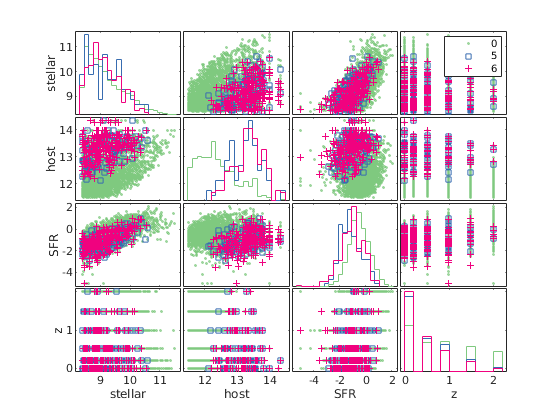

zz=illustris.utils.snap2redshift(objectTable.snap');
dataMat=cat(1,log10(galProps.galStellarMass),log10(galProps.hostM200c),log10(galProps.galSFR+1e-5),zz)';

labs={'stellar','host','SFR','z'};
score=tally6;
score(score<5)=0;

cc=brewermap(8,'Accent');

gplotmatrix(dataMat,[],score,cc([1 5 6],:),'ss+',[1.5,5,5],...
'on',[],labs,labs)

%printout_fig(gcf,'jf_perlim_scores56')

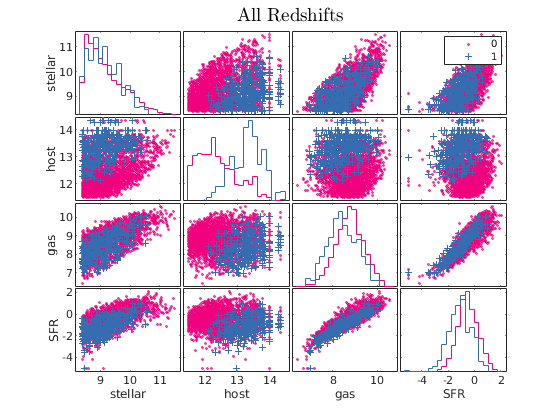



    dataMat=cat(1,log10(galProps.galStellarMass),log10(galProps.hostM200c),...
        log10(galProps.galGasMass),log10(galProps.galSFR+1e-5))';
    labs={'stellar','host','gas','SFR'};
    score=tally6;
    score(score<5)=0;
    score(score>=5)=1;
    cc=brewermap(8,'Accent');
    %% try out figure for scores 5 and 6
    figure;
    gplotmatrix(dataMat,[],score,cc([6 5],:),'s+',[1.5,5],...
        'on',[],labs,labs)
    titlemine('All Redshifts');

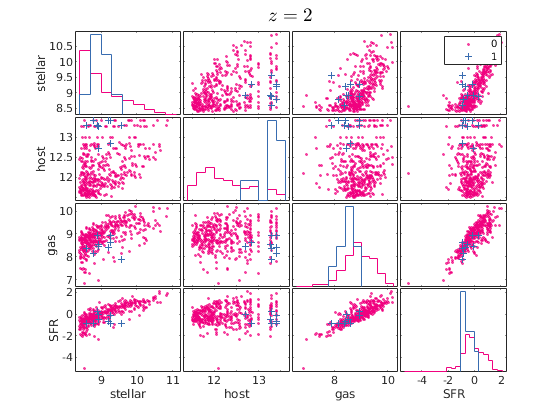

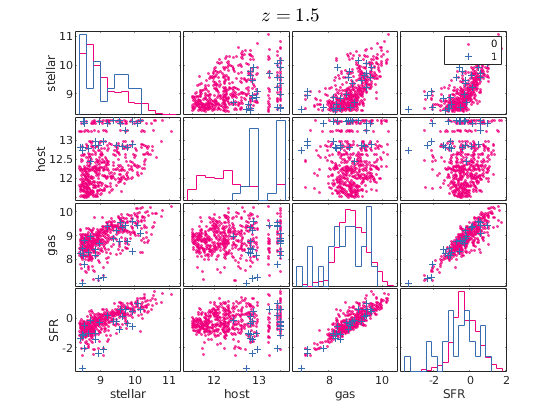

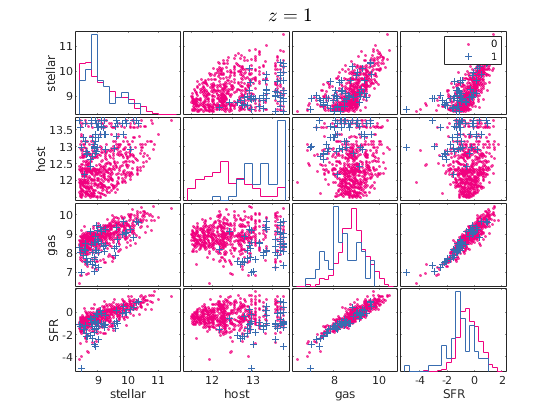

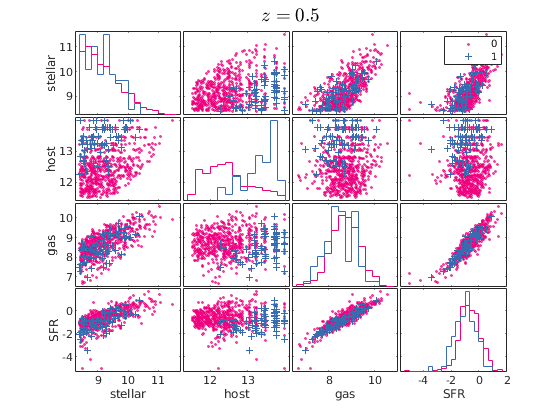

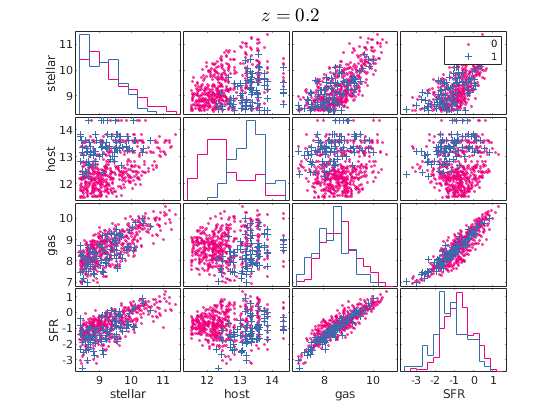

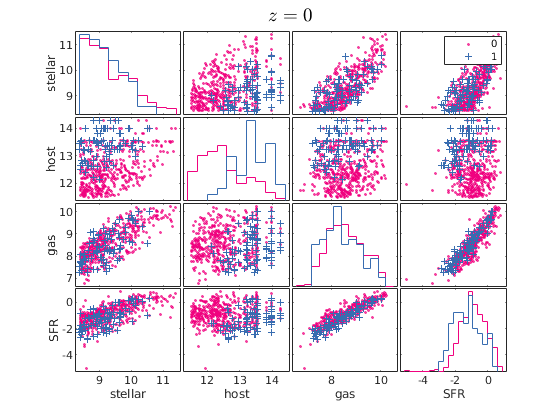



for i=1:length(snaps)
    inds=objectTable.snap==snaps(i);
    dataMat=cat(1,log10(galProps.galStellarMass(inds)),log10(galProps.hostM200c(inds)),...
        log10(galProps.galGasMass(inds)),log10(galProps.galSFR(inds)+1e-5))';
    labs={'stellar','host','gas','SFR'};
    score=tally6(inds);
    score(score<5)=0;
    score(score>=5)=1;
    cc=brewermap(8,'Accent');
    %% try out figure for scores 5 and 6
    figure;
    gplotmatrix(dataMat,[],score,cc([6 5],:),'s+',[1.5,5],...
        'on',[],labs,labs)
    titlemine(['$z=' num2str(zreds(i)) '$']);
end